# Filtr separujący

baseFreq = 96e6;
filter1spec = [baseFreq-1e6, baseFreq+1e6];

% terget
filter2spec = [baseFreq-100e3, baseFreq+100e3];
filter2stop = [baseFreq-100e3-20e3, baseFreq+100e3+20e3];

%one way
designSpecs = fdesign.bandpass(filter2stop(1), filter2spec(1), ...
    filter2spec(2),filter2stop(2), 40, 3, 40, 40e7)

designSpecs =   bandpass with properties:

               Response: 'Bandpass'
          Specification: 'Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2'
            Description: {7×1 cell}
    NormalizedFrequency: 0
                     Fs: 400000000
                 Fstop1: 95880000
                 Fpass1: 95900000
                 Fpass2: 96100000
                 Fstop2: 96120000
                 Astop1: 40
                  Apass: 3
                 Astop2: 40


bandpassFilt  = design(designSpecs,'ellip')

bandpassFilt =          FilterStructure: 'Direct-Form II, Second-Order Sections'                                                                                                                                                                                                                                                              
              Arithmetic: 'double'                                                                                                                                                                                                                                                                                             
               sosMatrix: [1 -0.129237637905714 1 1 -0.128666057082192 0.999916976974648;1 -0.121923907069399 1 1 -0.122485301696892 0.999916960798951;1 -0.130538924090366 1 1 -0.127880864431804 0.99958642611226;1 -0.120621913957076 1 1 -0.123229241630951 0.999586365470805;1 0 -1 1 -0.125531645941523 0.99921090021385]
             ScaleValues:

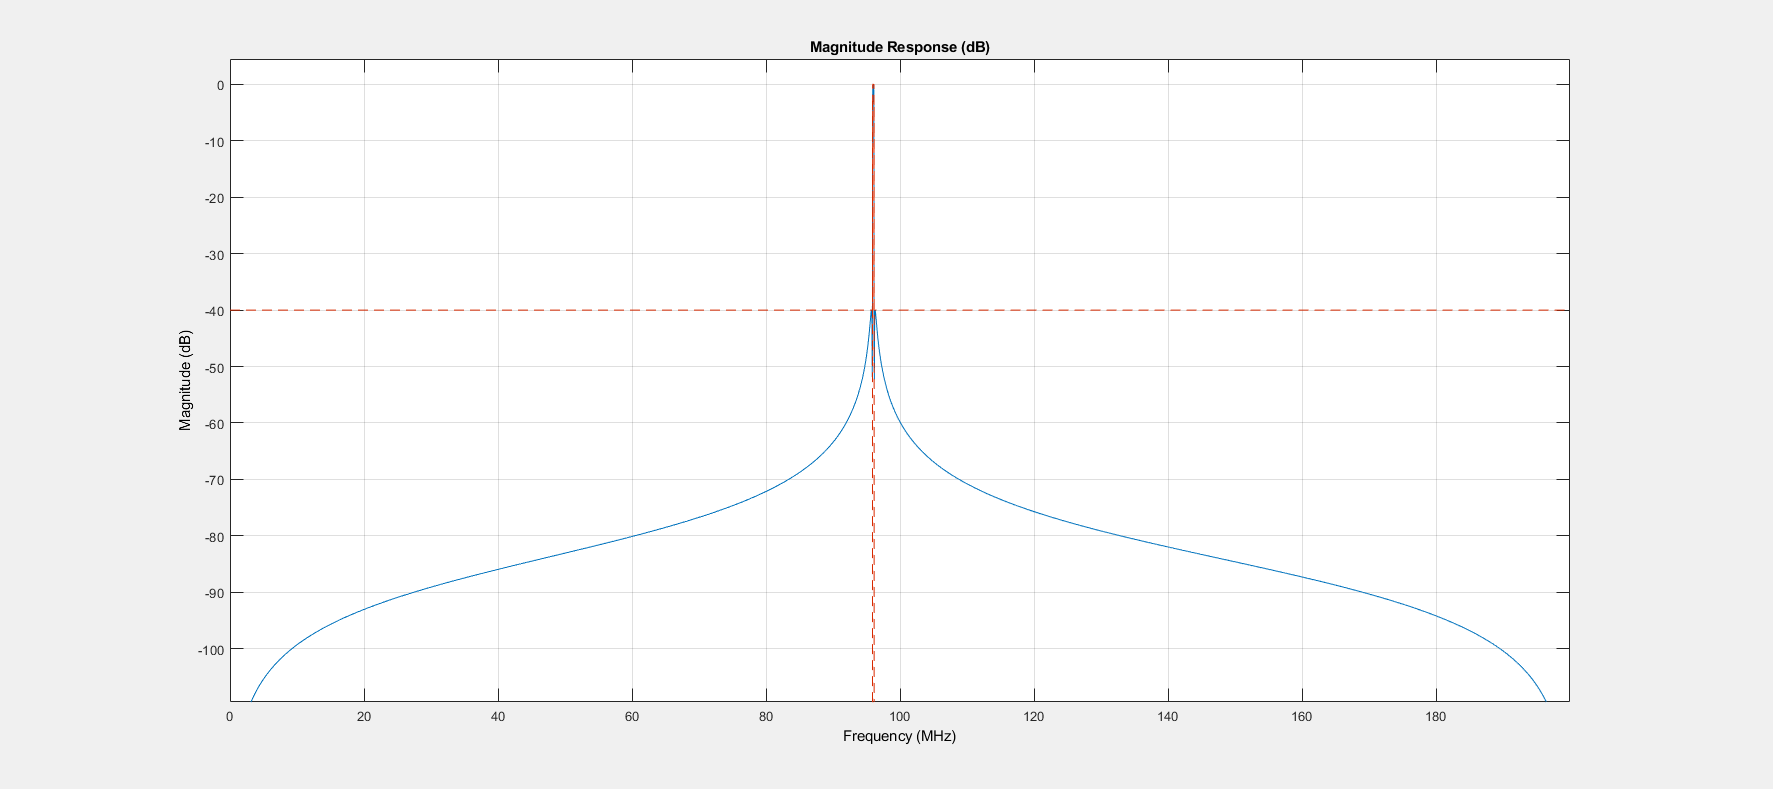

fvtool(bandpassFilt)

%another way
 